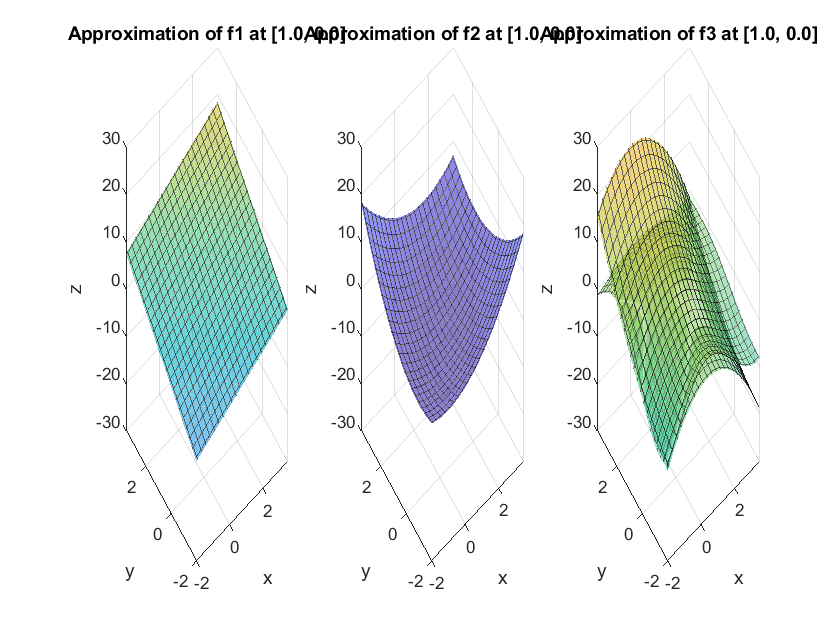

close all; clc;

%[x,y]=meshgrid(-2:0.2:3.5, -2:0.2:3.5);
syms x y;
f1 = 2*x+3*y+1;
f2 = x.^2+y.^2-x.*y-5;
f3 = (x-5)*cos(y-5)-(y-5)*sin(x-5);

g1 = gradient(f1,[x,y]);
g2 = gradient(f2,[x,y]);
g3 = gradient(f3,[x,y]);

h1 = hessian(f1,[x,y]);
h2 = hessian(f2,[x,y]);
h3 = hessian(f3,[x,y]);


%%%%%Quadratic Approximation at (1,0)
figure(1)
plotQuadApprox(x,y,1,0,f1,g1,h1,1)
plotQuadApprox(x,y,1,0,f2,g2,h2,2)
plotQuadApprox(x,y,1,0,f3,g3,h3,3)

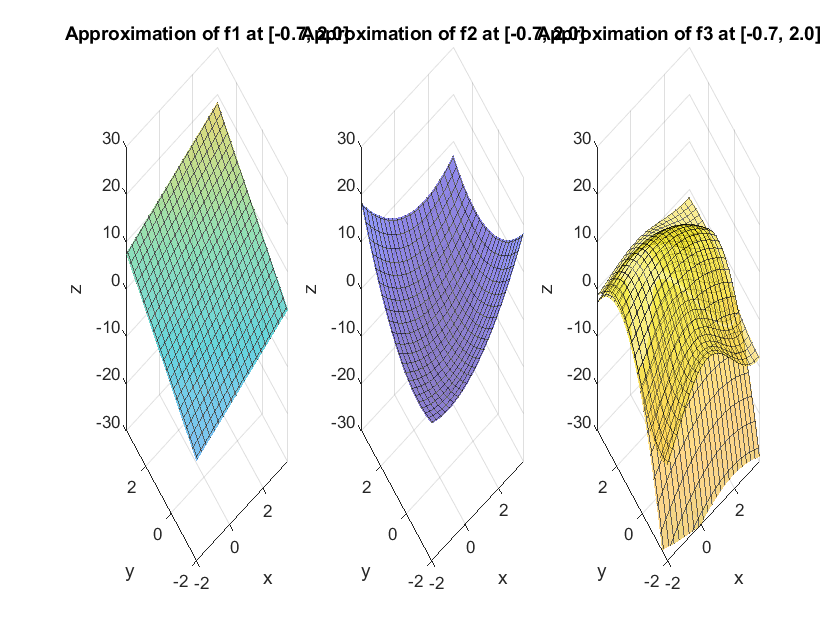


%%%%%Quadratic Approximation at (-0.7,2)
figure(2)
plotQuadApprox(x,y,-0.7,2,f1,g1,h1,1)
plotQuadApprox(x,y,-0.7,2,f2,g2,h2,2)
plotQuadApprox(x,y,-0.7,2,f3,g3,h3,3)

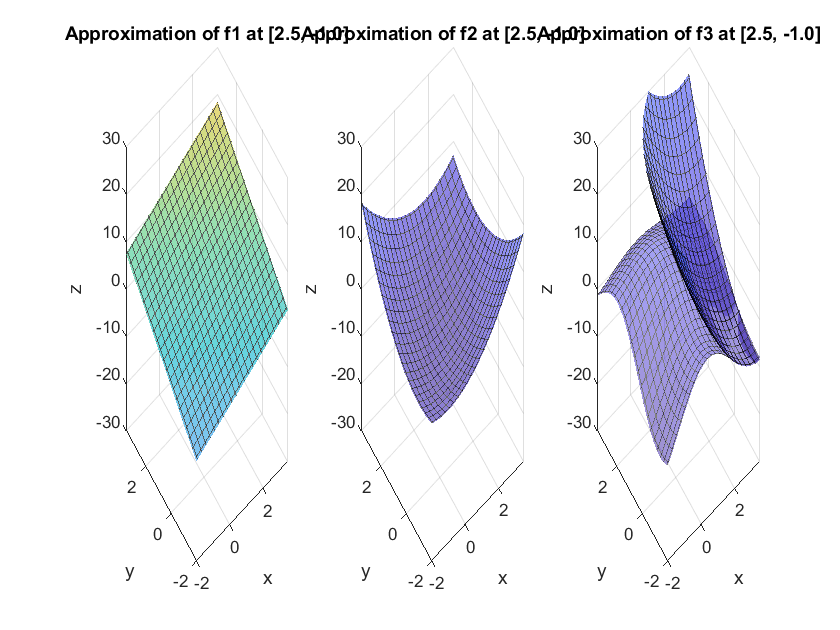


%%%%%Quadratic Approximation at (2.5,-1)
figure(3)
plotQuadApprox(x,y,2.5,-1,f1,g1,h1,1)
plotQuadApprox(x,y,2.5,-1,f2,g2,h2,2)
plotQuadApprox(x,y,2.5,-1,f3,g3,h3,3)

function plotQuadApprox(x,y,v1,v2,f,g,h,subPlotInd)
subplot(1,3,subPlotInd);
V = [x,y]';
V0 = [v1,v2]';
f_v0 = subs(f,[x,y],[v1,v2]);
g_v0 = subs(g,[x,y],[v1,v2]);
h_v0 = subs(h,[x,y],[v1,v2]);

f_approx = f_v0 + g_v0'*(V-V0) + 0.5*(V-V0)'*h_v0*(V-V0);

p1 = ezsurf(x,y,f);
set(p1,'facealpha',0.5)
set(p1,'edgealpha',0.5)
axis([-2 3.5 -2 3.5 -30 30])
hold on
p2 = ezsurf(x,y,f_approx);
set(p2,'facealpha',0.6)
set(p2,'edgealpha',0.6)
axis([-2 3.5 -2 3.5 -30 30])

xlabel('x');
ylabel('y');
zlabel('z');
title(sprintf('Approximation of f%d at [%.1f, %.1f]', subPlotInd, v1, v2));
end